# Experimento do corpo - Selecionado

## Importar dados

clear
load exp_corpo.mat

## Cabeçalho

f = freq;
ts = 0.01;
ti = 0:ts:ts*length(u)-ts;

opt = procestOptions("InitialCondition", "zero");
l_tempo = "Tempo(s)";
l_pos = "Posição(rad)";
l_vel = "Velocidade(rad/s)";
l_frad = "Frequência(rad/s)";
l_gdec = "|G| dB";
l_em = ["Experimento", "Modelo"];
t_el = "Encoder Esquerdo";
t_er = "Encoder Direito";
t_mpu = "MPU";

### Dados de simulação e entrada

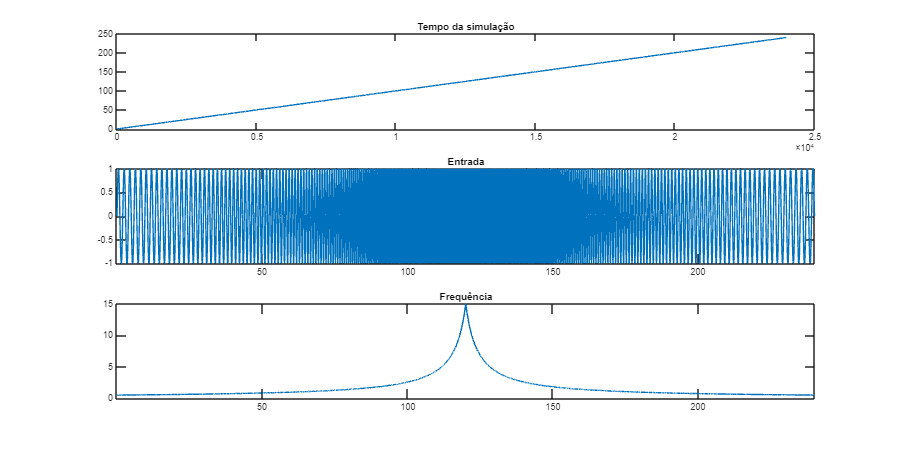

figure("Position", [403 146 1200 600])
limx = [t(1) t(end)];

subplot(3,1,1); plot(t);                title("Tempo da simulação"); 
subplot(3,1,2); plot(t, u); xlim(limx); title("Entrada"); 
subplot(3,1,3); plot(t, f); xlim(limx); title("Frequência"); 

## Modelagem por dados de posição

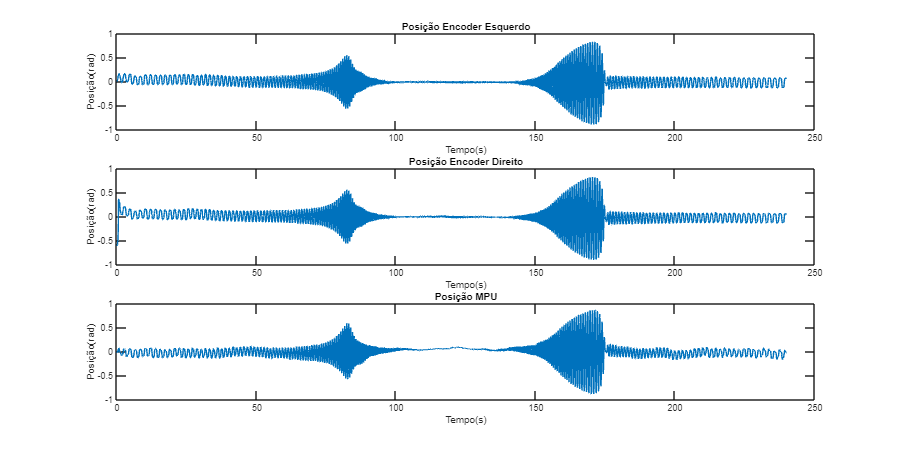

figure("Position", [403 146 1200 600])

subplot(3,1,1); plot(t, yl);    ylabel(l_pos); xlabel(l_tempo); title("Posição " + t_el); 
subplot(3,1,2); plot(t, yr);    ylabel(l_pos); xlabel(l_tempo); title("Posição " + t_er); 
subplot(3,1,3); plot(t, theta); ylabel(l_pos); xlabel(l_tempo); title("Posição " + t_mpu);

### Seleção dos dados

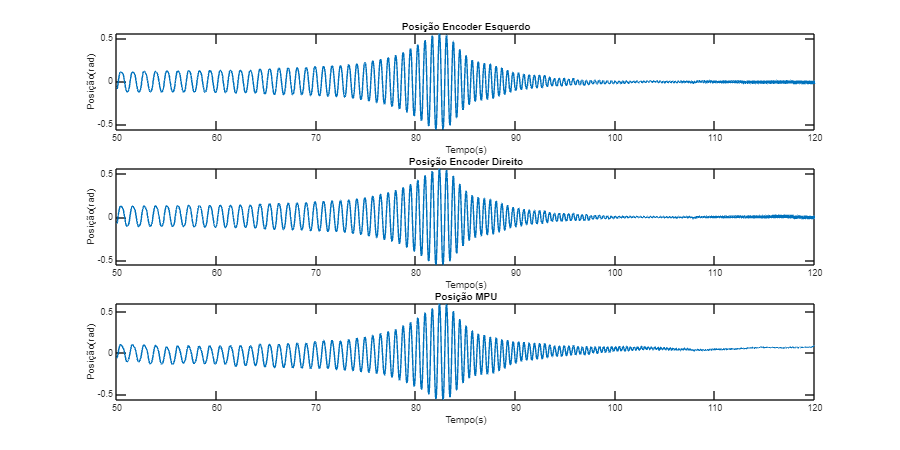

idx = t>t(50) & t<120;
limx = [50 120];

figure("Position", [403 146 1200 600])

subplot(3,1,1); plot(t, yl);      ylabel(l_pos); xlabel(l_tempo); xlim(limx); title("Posição " + t_el); 
subplot(3,1,2); plot(t, yr);      ylabel(l_pos); xlabel(l_tempo); xlim(limx); title("Posição " + t_er); 
subplot(3,1,3); plot(t, theta);   ylabel(l_pos); xlabel(l_tempo); xlim(limx); title("Posição " + t_mpu);

### Estimativa do modelo de posição

d_encl = iddata(yl(idx), u(idx), ts);
d_encr = iddata(yr(idx), u(idx), ts);
d_mpu =  iddata(theta(idx), u(idx), ts);
G_encl = tf(tfest(d_encl, 2, 0))

G_encl =
 
  From input "u1" to output "y1":
          5.176
  ---------------------
  s^2 + 1.205 s + 76.94
 
Continuous-time transfer function.
Model Properties


G_encr = tf(tfest(d_encr, 2, 0))

G_encr =
 
  From input "u1" to output "y1":
          5.209
  ---------------------
  s^2 + 1.203 s + 76.98
 
Continuous-time transfer function.
Model Properties


G_mpu = tf(tfest(d_mpu, 2, 0))

G_mpu =
 
  From input "u1" to output "y1":
          4.811
  ---------------------
  s^2 + 1.075 s + 76.69
 
Continuous-time transfer function.
Model Properties


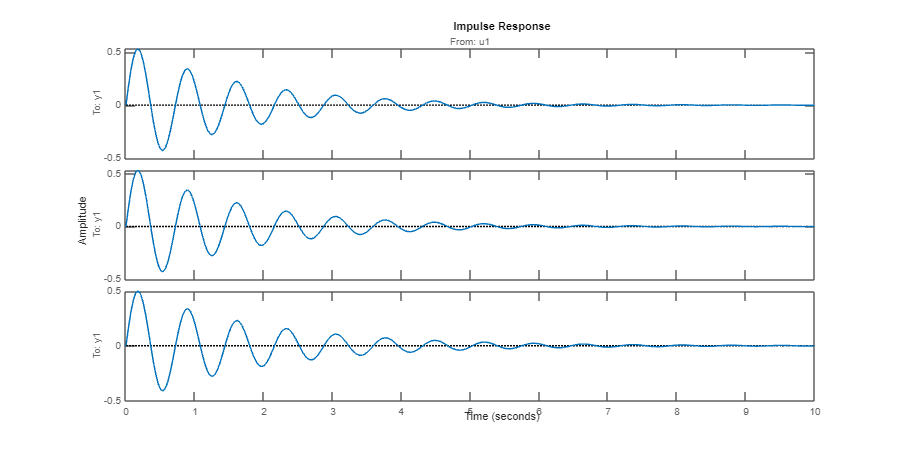

figure("Position", [403 146 1200 600])

impulse([G_encl; G_encr; G_mpu])

#### Comparação com modelo 

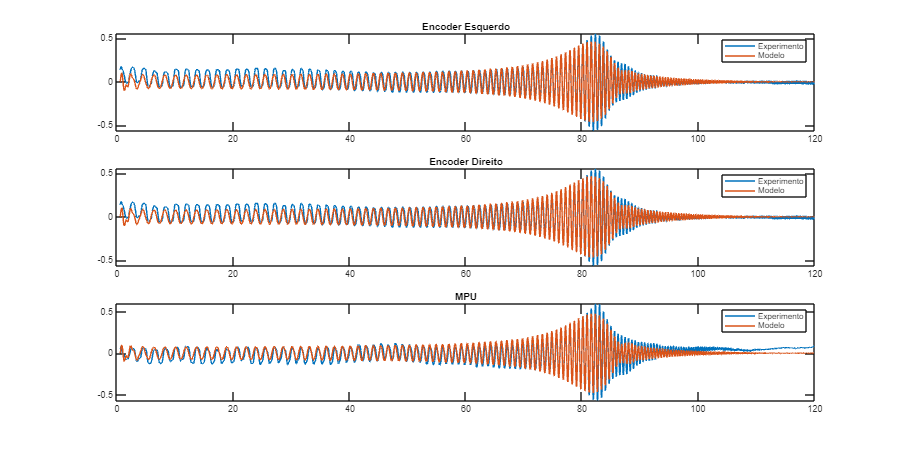

y_encl = lsim(G_encl, u(idx), ti(idx));
y_encr = lsim(G_encr, u(idx), ti(idx));
y_mpu  = lsim(G_mpu, u(idx), ti(idx));

figure("Position", [403 146 1200 600])
limx = [0 120];

subplot(3,1,1); plot(ti(idx), yl(idx));     title(t_el); hold on; plot(ti(idx), y_encl); xlim(limx); legend(l_em);
subplot(3,1,2); plot(ti(idx), yl(idx));     title(t_er); hold on; plot(ti(idx), y_encr); xlim(limx); legend(l_em); 
subplot(3,1,3); plot(ti(idx), theta(idx));  title(t_mpu); hold on; plot(ti(idx), y_mpu); xlim(limx); legend(l_em); 

## Modelagem por dados de velocidade

figure("Position", [403 146 1200 600])
limy = [min([min(dyl),min(dyr),min(dtheta)]) max([max(dyl),max(dyr),max(dtheta)])]

limy =    -7.1454    7.3196


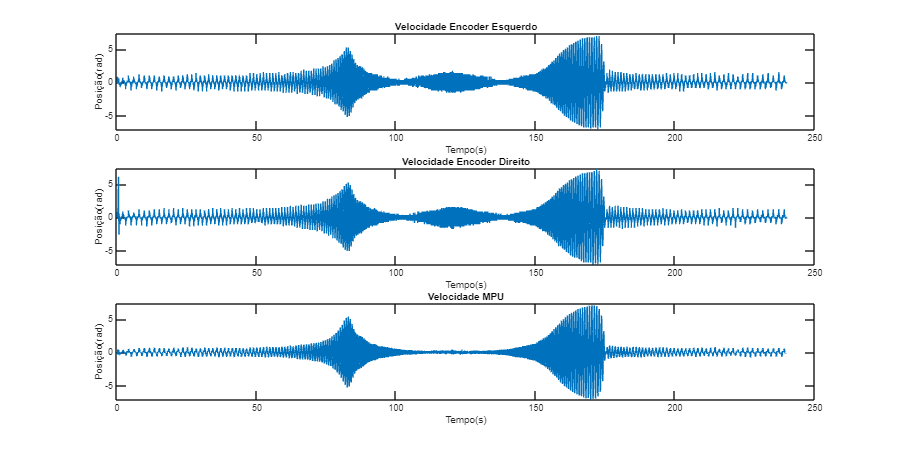


subplot(3,1,1); plot(t, dyl);    ylabel(l_pos); ylim(limy); xlabel(l_tempo); title("Velocidade " + t_el); 
subplot(3,1,2); plot(t, dyr);    ylabel(l_pos); ylim(limy); xlabel(l_tempo); title("Velocidade " + t_er); 
subplot(3,1,3); plot(t, dtheta); ylabel(l_pos); ylim(limy); xlabel(l_tempo); title("Velocidade " + t_mpu);

### Seleção dos dados

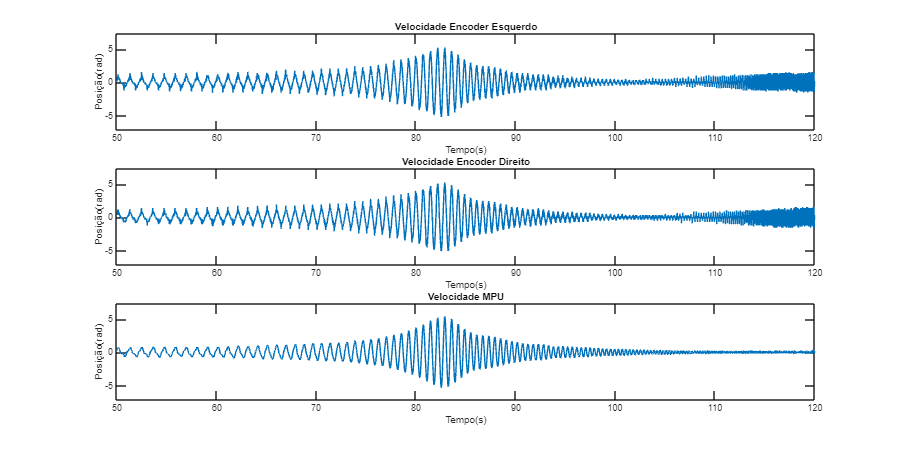

idx = t>t(50) & t<120;
limx = [50 120];

figure("Position", [403 146 1200 600])

subplot(3,1,1); plot(t, dyl);      ylabel(l_pos); xlabel(l_tempo); xlim(limx); ylim(limy); title("Velocidade " + t_el); 
subplot(3,1,2); plot(t, dyr);      ylabel(l_pos); xlabel(l_tempo); xlim(limx); ylim(limy); title("Velocidade " + t_er); 
subplot(3,1,3); plot(t, dtheta);   ylabel(l_pos); xlabel(l_tempo); xlim(limx); ylim(limy); title("Velocidade " + t_mpu);

### Estimativa do modelo de posição

d_enclv = iddata(dyl(idx), u(idx), ts);
d_encrv = iddata(dyr(idx), u(idx), ts);
d_mpuv  =  iddata(dtheta(idx), u(idx), ts);
G_enclv = tf(tfest(d_enclv, 2, 1))

G_enclv =
 
  From input "u1" to output "y1":
     5.087 s + 7.019
  ---------------------
  s^2 + 1.163 s + 78.37
 
Continuous-time transfer function.
Model Properties


G_encrv = tf(tfest(d_encrv, 2, 1))

G_encrv =
 
  From input "u1" to output "y1":
     5.097 s + 6.578
  ---------------------
  s^2 + 1.156 s + 78.31
 
Continuous-time transfer function.
Model Properties


G_mpuv  = tf(tfest(d_mpuv, 2, 1))

G_mpuv =
 
  From input "u1" to output "y1":
    5.189 s + 8.594
  --------------------
  s^2 + 1.154 s + 78.6
 
Continuous-time transfer function.
Model Properties


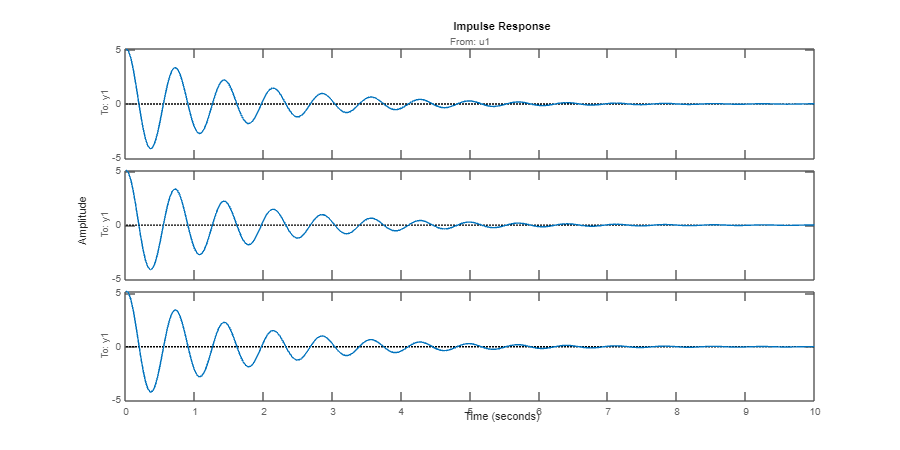

figure("Position", [403 146 1200 600])

impulse([G_enclv; G_encrv; G_mpuv])

#### Comparação com modelo 

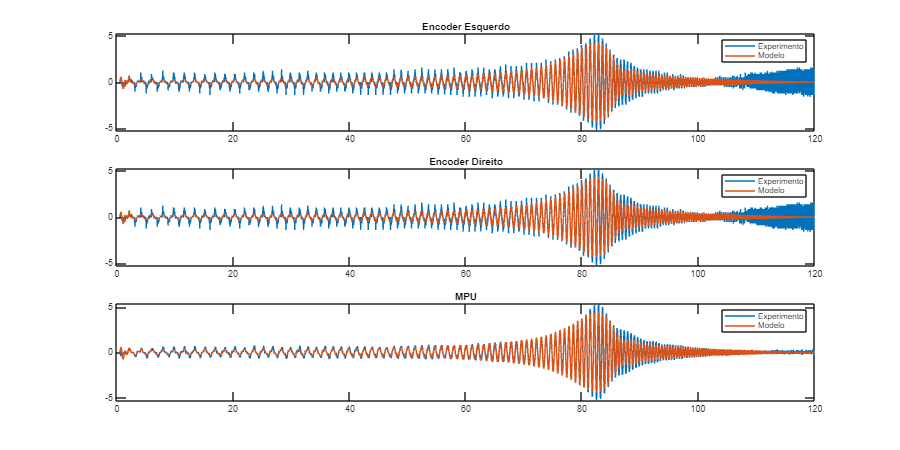

y_enclv = lsim(G_enclv, u(idx), ti(idx));
y_encrv = lsim(G_encrv, u(idx), ti(idx));
y_mpuv  = lsim(G_mpuv, u(idx), ti(idx));

figure("Position", [403 146 1200 600])
limx = [0 120];

subplot(3,1,1); plot(ti(idx), dyl(idx));     title(t_el); hold on; plot(ti(idx), y_enclv); xlim(limx); legend(l_em);
subplot(3,1,2); plot(ti(idx), dyl(idx));     title(t_er); hold on; plot(ti(idx), y_encrv); xlim(limx); legend(l_em); 
subplot(3,1,3); plot(ti(idx), dtheta(idx));  title(t_mpu); hold on; plot(ti(idx), y_mpuv); xlim(limx); legend(l_em); 

## Exportar dados

- O modelo escolhido foi o de velocidade para a MPU;

zpk(G_mpuv)

ans =
 
  From input "u1" to output "y1":
    5.1894 (s+1.656)
  ---------------------
  (s^2 + 1.154s + 78.6)
 
Continuous-time zero/pole/gain model.
Model Properties


zeros = ans.Z{1}, ...
polos = ans.P{1}, ...
K_corpo = ans.K

zeros = -1.6560

polos =   -0.5771 + 8.8471i
  -0.5771 - 8.8471i


K_corpo = 5.1894

polos(1) + polos(2)

ans = -1.1542

omega = sqrt(polos(1) * polos(2))

omega = 8.8659

zeta = -(polos(1) + polos(2)) / (2 * omega)

zeta = 0.0651

K_corpo = K_corpo/omega^2

K_corpo = 0.0660

save("tf_corpo.mat", "K_corpo", "omega", "zeta")